# Lab 3 - Intensity Transformation and Spatial Filtering

This lab focuses on intensity transformations and spatial filtering.

As Design Engineers, it is more important for you to understand the principles and then use ready-made libraries to perform processing on visual data, than to write low-level code to implement the algorithms.

> How would you actually write these low-level algorithms?

## Task 1 - Contrast enhancement with function imadjust

### Image Info

imfinfo('assets/breastXray.tif')

ans = struct with fields:
                     Filename: '/Users/marci/Documents/MATLAB/DVS-labs/lab-3/assets/breastXray.tif'
                  FileModDate: '25-Jan-2026 17:31:37'
                     FileSize: 275657
                       Format: 'tif'
                FormatVersion: []
                        Width: 482
                       Height: 571
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [25 10147 20269 30391 40513 50635 60757 70879 81001 91123 101245 111367 121489 131611 141733 151855 161977 172099 182221 192343 202465 212587 222709 232831 242953 253075 263197 273319]
              SamplesPerPixel: 1
                 RowsPerStrip: 21
              StripByteCounts: [10

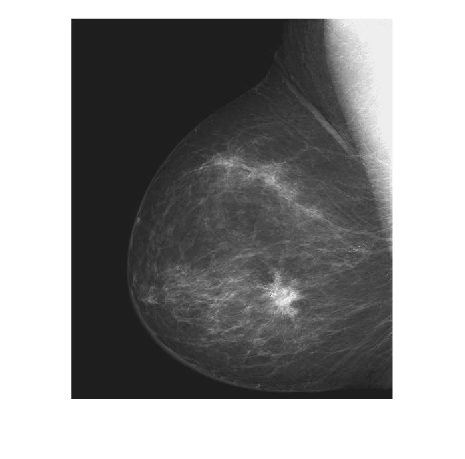

f = imread('assets/breastXray.tif');
imshow(f);

Image info includes useful data such as file size, width, height, bit depth, colour type, byte order, compression etc. > What is little-edian?

The width = 482; Half = 241

Height = 571; Half = 285.5

f(3,10)             % print the intensity of pixel(3,10)

ans = uint8
28

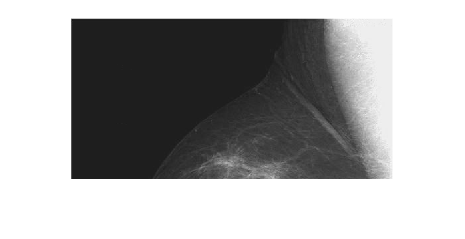

imshow(f(1:241,:))  % display only top half of the image

Indices of 2D matrix in Matlab is of the format: (row, column). You can use *':'* to *slice* the data. *(1:241 , : )* means only rows 1 to 241 and all columns are used. The default is the entire matrix.

Finding maxium and minimum intensity values:

[fmin, fmax] = bounds(f(:))

fmin = uint8
21

fmax = uint8
255

The index ( : ) means every column. If notr specified, MATLAB will rreturn the max and min values for each column as 2 row vectors. - this could cause problems if the image is really big? e.g. high amount of printed output which is time consuming

Since the data type for *f* is *uint8*, the full intensity range is [0 255]. Is the intensity of *f* close to the full range?

The lowest value is 21, and the highest value is 255. This means there is no true black (0) value in the image, only very dark grey values. 

Displaying only the right half of the image:

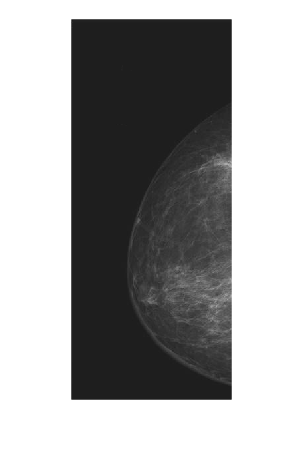

imshow(f(1:571,1:482/2)) 

imshow(f(:,1:241)) 

% this can be achieved in multiple ways but the second option is cleaner

### Negative Image

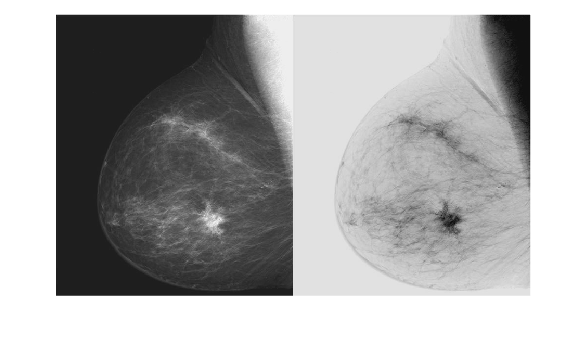

g1 = imadjust(f, [0 1], [1 0]);
montage({f, g1});

> Think a bit more about what `imadjust` is doing here

The second parameter of imadjust is in the form `[low_in, high_in]` - the values are between 0 and 1. [0 1] Means that the input image is being adjusted to within 1% of the bottom and top pixel values.

> And what does that mean?

The 3rd parameter is also in the form `[low_out, high_out]`

It spcifies how the input range is mapped to the output range. [1 0] means the lowest pixel intensity of the input is now mapped to the highest pixel intensity of the output and vice versa. This is why all the intensities are inverted and a negative image is produced.

The same thing can be achieved using function imcomplement 

> This is finding the complement of the image?

Trying out different adjustements:

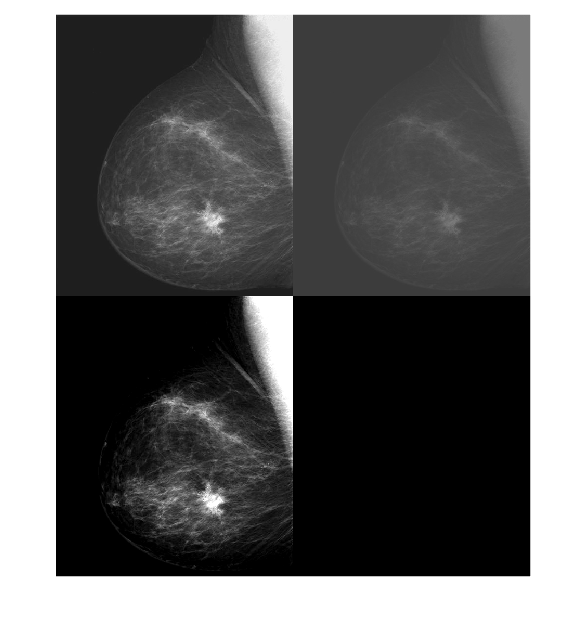

f = imread('assets/breastXray.tif');
g2 = imadjust(f, [0 1], [0.2 0.5]);

%this allows you to darken the black values and brighten the white values:
g3 = imadjust(f, [0.2 0.8], [0 1]); 
montage({f, g2, g3});

### Gamma Correction - Need to Review this Part [!!!]

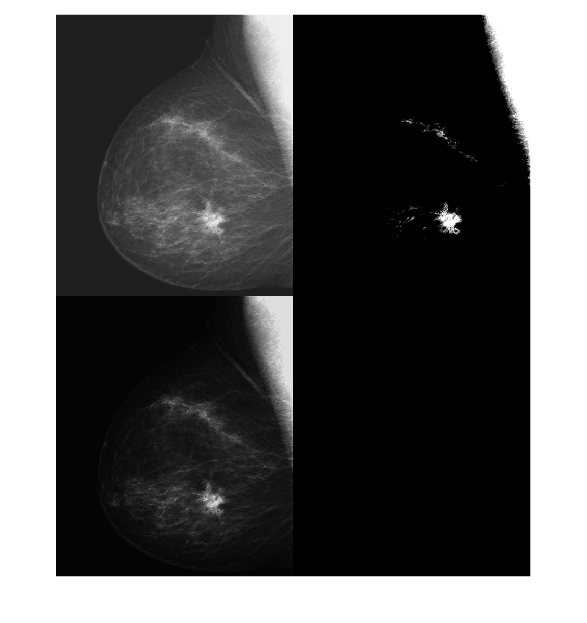

g2 = imadjust(f, [0.5 0.75], [0 1]); 
g3 = imadjust(f, [ ], [ ], 2);
figure
montage({f,g2,g3})

> What is actually happening in gamma correction? How does the operation work, perform etc.?

How do you operate it in a useful way?

This produces a result similar to that of g2 by compressing the low end and expanding the high end of the gray scale. It however, unlike g2, retains more of the details because the intensity now covers the entire gray scale range.

*g3* uses gamma correct with gamma = 2.0 as shown in the diagram below. [ ] is the same as [0 1] by default.

Explore in a bit more detail how imadjust works

## Task 2

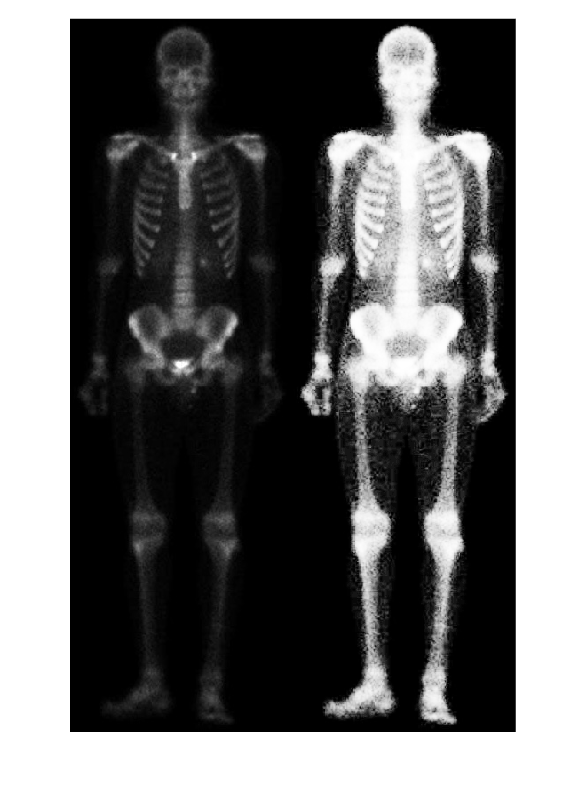

f = imread('assets/bonescan-front.tif');
r = double(f);  % uint8 to double conversion
k = mean2(r);   % find mean intensity of image
E = 2;
s = 1 ./ (1.0 + (k ./ (r + eps)) .^ E);


g = uint8(255*s);
imshowpair(f, g, "montage")


$$s=T\left(r\right)=\frac{\left\lbrack 1\right\rbrack }{1+{\left(\frac{k}{r}\right)}^E }$$


E determines the steepness of the function. `eps` is a specal MATLAB constant which has the smallest value possible for double precision floating point numbers. This is necessary to avoid division by zero - maybe this could be useful in other applications too.

> Why do we perform the conversion to a double?

> How does element-by-element operation work here - it just seems like an equation

The intensity values of s are normalized to the range of [0.0 1.0] and is in type *double*. Finally we scale this back to the range [0 255] and covert back to *uint8*.

> Why? Why are the intensity values stored as  [0.0 1.0]  - where did this take place?

**Discussion of results:**

The white parts of the image are much brighter - the contrast has been stretched enabling more of the skeleton features to be visible. 

## Task 3 - Contrast Enhancement using Histogram

Matlab has a built-in function *imhist* to compute the histogram of an image and plot it.

### Plotting the histogram of an image

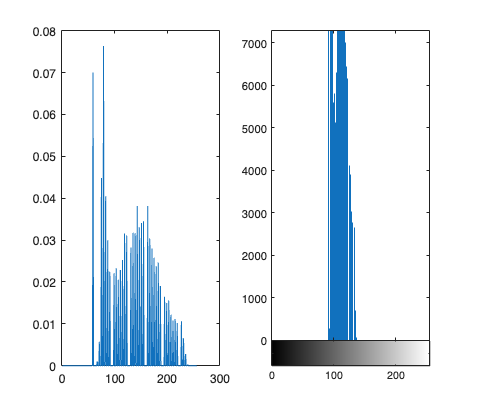

f=imread('assets/pollen.tif');
imshow(f)
imhist(f);      % calculate and plot the histogram

The intensity level of this image is squashed between 70 to 140 in the range [0 355]. We may want to stretch this intensity to help improve the quality of the image. This can be done using the imadjust function. 

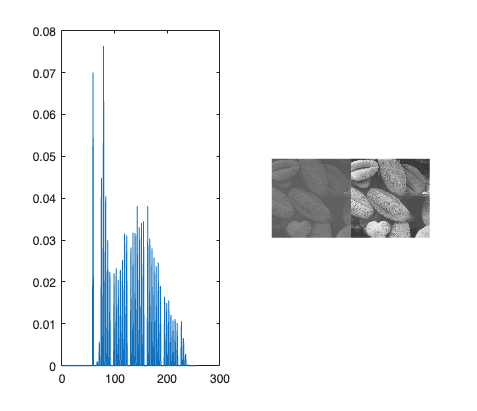

g=imadjust(f,[0.3 0.55]); 
% why are these numbers selected?
% how does imadjust work in this format?

montage({f, g})     % display list of images side-by-side

imhist(f);

imhist(g);

This spreads out the histogram - but still not to the full range.

### Histogram, PDF and CDF

PDF is the normalised histogram - how does normalisation work here?

CDF is an integration of the cumulative sum of the PDF

numel returns the total number of elements in the matrix

> Do some more reading on this not sure if I fully get it especially the formulas

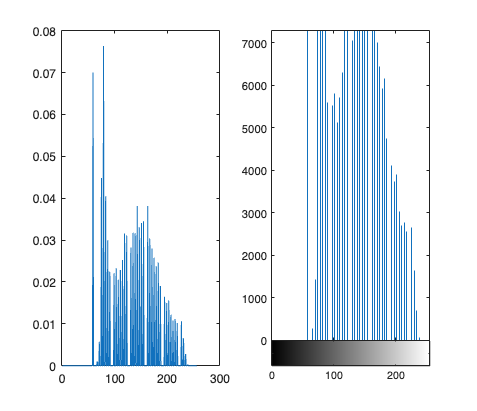

g_pdf = imhist(g) ./ numel(g);  % compute PDF
g_cdf = cumsum(g_pdf);          % compute CDF

subplot(1,2,1)                  % plot 1 in a 1x2 subplot
plot(g_pdf)

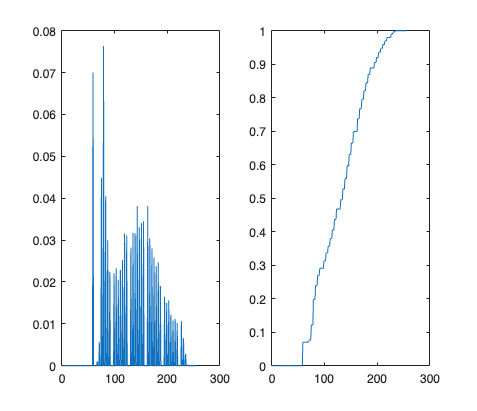

subplot(1,2,2)                  % plot 2 in a 1x2 subplot
plot(g_cdf)

### Histogram Equalisation

To perform histogram equalisation the CDF is used as the intensity transformation function

> Why?

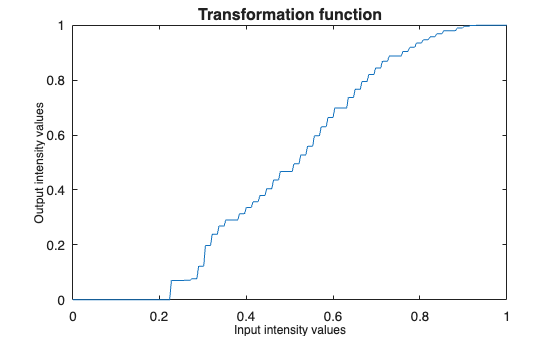

x = linspace(0, 1, 256);    % x has 256 values equally spaced
                            %  .... between 0 and 1
figure
plot(x, g_cdf)
axis([0 1 0 1])             % graph x and y range is 0 to 1
set(gca, 'xtick', 0:0.2:1)  % x tick marks are in steps of 0.2
set(gca, 'ytick', 0:0.2:1)
xlabel('Input intensity values', 'fontsize', 9)
ylabel('Output intensity values', 'fontsize', 9)
title('Transformation function', 'fontsize', 12)

histeq computes the CDF of an image and uses this as the intensity transformation function to flatten the histogram - this happens behind the scenes in MATLAB 

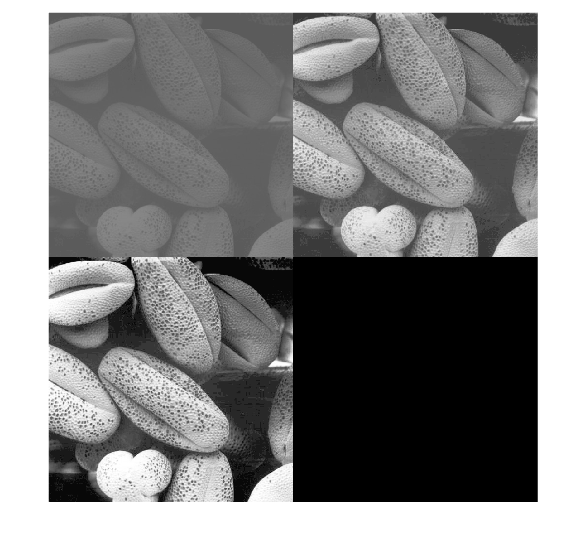

h = histeq(g,256);              % histogram equalize g
montage({f, g, h})

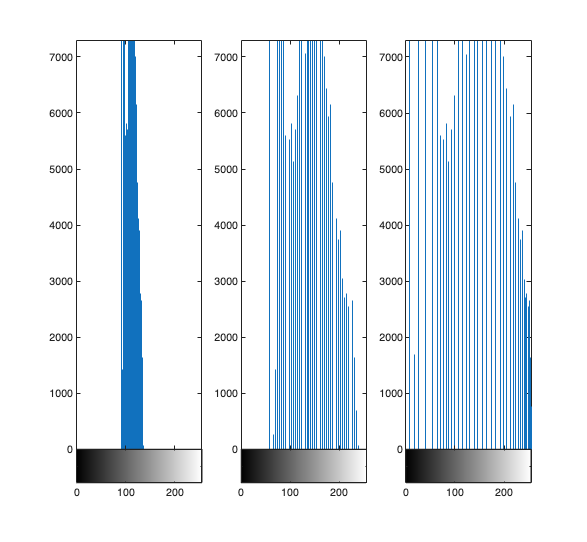

subplot(1,3,1); imhist(f);
subplot(1,3,2); imhist(g);
subplot(1,3,3); imhist(h);

## Task 4 - Noise Reduction with lowpass Filter - [REVIEW!]

Different types of filter kernels: Averaging (box), Gaussian, Laplacian and Sobel. 

Types of kernels::

- 'average'

- 'disk'

- 'gaussian'

- 'laplacian'

- 'log'

- 'motion'

- 'prewitt'

- 'sobel'

- 'unsharp'

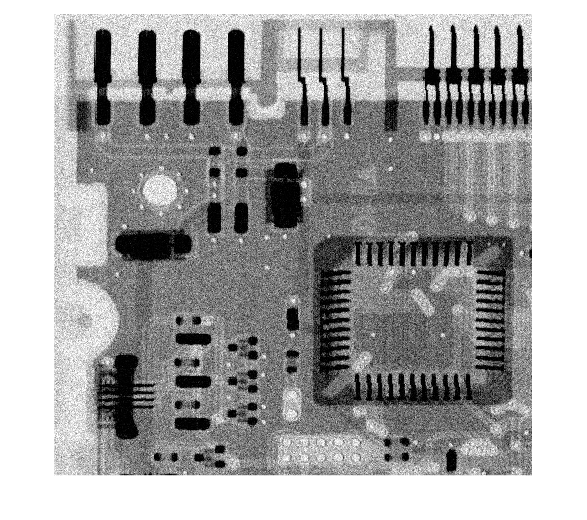

clear all
close all
f = imread('assets/noisyPCB.jpg');
% xray of printed circuit board
imshow(f)

> How do Gaussian kernels work and why choose these specific values:

w_box = fspecial('average', [9 9])

w_box =     0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123


w_gauss = fspecial('Gaussian', [7 7], 1.0)

w_gauss =     0.0000    0.0002    0.0011    0.0018    0.0011    0.0002    0.0000
    0.0002    0.0029    0.0131    0.0216    0.0131    0.0029    0.0002
    0.0011    0.0131    0.0586    0.0966    0.0586    0.0131    0.0011
    0.0018    0.0216    0.0966    0.1592    0.0966    0.0216    0.0018
    0.0011    0.0131    0.0586    0.0966    0.0586    0.0131    0.0011
    0.0002    0.0029    0.0131    0.0216    0.0131    0.0029    0.0002
    0.0000    0.0002    0.0011    0.0018    0.0011    0.0002    0.0000


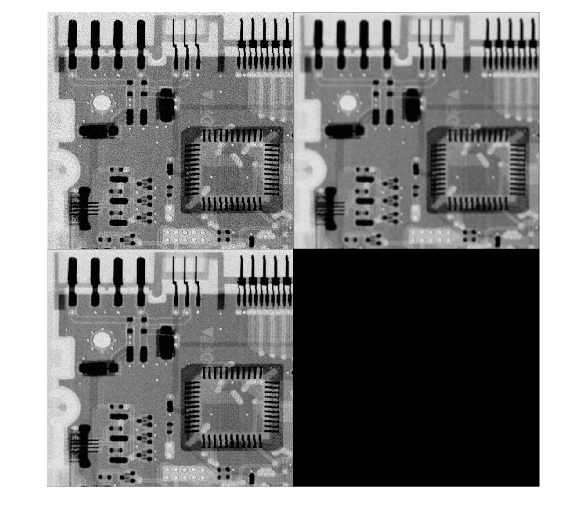

%  Note that the coefficients are scaled in such a way that they sum to 1.
%  where...?

g_box = imfilter(f, w_box, 0);
g_gauss = imfilter(f, w_gauss, 0);

montage({f, g_box, g_gauss})

Test yourself: Explore various kernel size and sigma value for these two filters. Comment on the trade-off between the choice of these parameters and the effect on the image.

## Task 5 - Median Filtering

In both cases with Average and Gaussian filters, noise reduction is companied by reducing in the sharpness of the image. Median filter provides a better solution if sharpness is to be preserved. 

> How does median filtering actually work? How do you choose the different parameters?

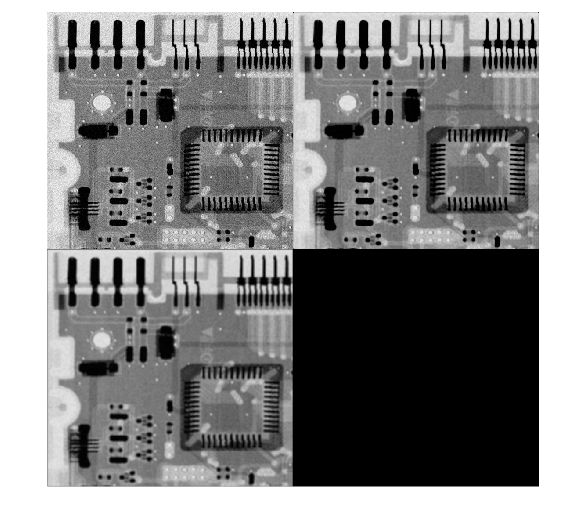

g_median = medfilt2(f, [7 7], 'zero');
montage({f, g_median, g_box})

You can visibly see the image is less blurry - but why is this the case?